clear all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');


% london_outer_table=readtable('london_outer.csv');
% london_inner_table=readtable('london_inner.csv');

xy_ref= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_ref= s_opt_table.x_S_opt;
s_ref_cum= cumsum(s_ref);


dt= 0.025; % stepwise
t= (0:dt:0.5)'; % total time
u_steer= deg2rad([-15:1:15]);
state0= [xy_ref(1,1); xy_ref(1,1) ; 0; 0];

s_path_cum= 0;

select_path_index_list= [];
states_end_list= [];
u_f_dri_list=[];
u_burn_list=[];
s_cum= 0;

% for iter= 1:400
while(s_cum< s_ref_cum(end))
s_path_list= []; % store length of each path

%%% generate paths of different control inputs
for i=1:length(u_steer)
    [states, f_dri, burn] = EngineModel(state0, u_steer(i), t, dt);
    
    %%% compute each path length
    x= states(1,:);
    y= states(2,:);
    %states_end= states(:,end);
    s_path= 0;
    
    for k= 1:length(x)-1
        s_path= s_path+ norm([x(k+1)- x(k), y(k+1)-y(k)],2);
    end
    
    s_path_list= [s_path_list; s_path];
    
end

%%% find point on the ref path
s_path_cum= s_path_cum+ max(s_path_list); % running distance of paths
s_tmp= 0;
index_ref= 1;
while(s_tmp< s_path_cum)
    if index_ref> length(s_ref)
        break;
    end
    
    s_tmp= s_tmp+ s_ref(index_ref);
    
    index_ref= index_ref+1;
end

s_cum= s_tmp;

%%% select the path closest to ref
index_ref= index_ref-1;
[select_path_index, states_select, u_f_dri, u_burn] = SelectPath(u_steer, xy_ref(index_ref, 1:2), state0, t, dt);

select_path_index_list= [select_path_index_list; select_path_index];
state0= states_select(:,end);
states_end_list= [states_end_list, states_select(:,end)];
u_burn_list= [u_burn_list, u_burn];
u_f_dri_list= [u_f_dri_list, u_f_dri];

end

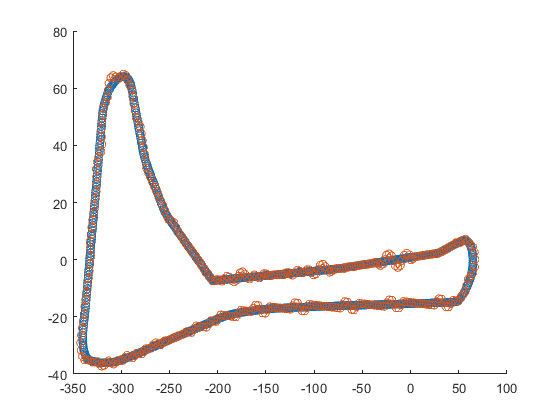

close all;
plot_num= 1:940;
figure()
scatter(path_opt_table.x_Traj_x(plot_num), path_opt_table.traj_y(plot_num));
hold on;
plot(states_end_list(1,:),states_end_list(2,:), 'o-');
hold off;

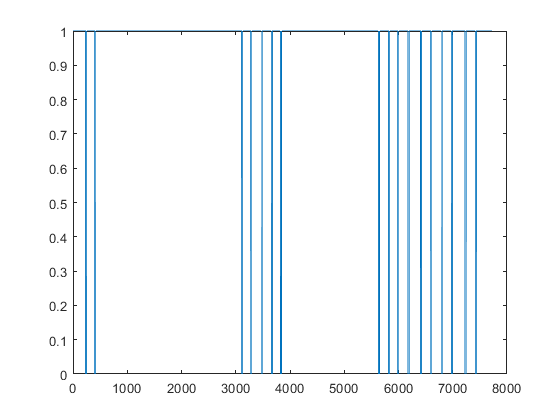


figure();
plot(u_burn_list);

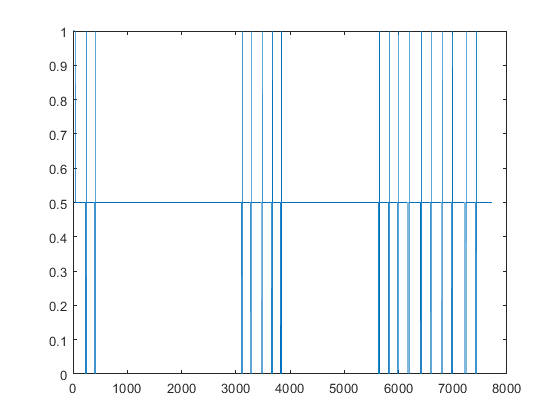


figure();
plot(u_f_dri_list);

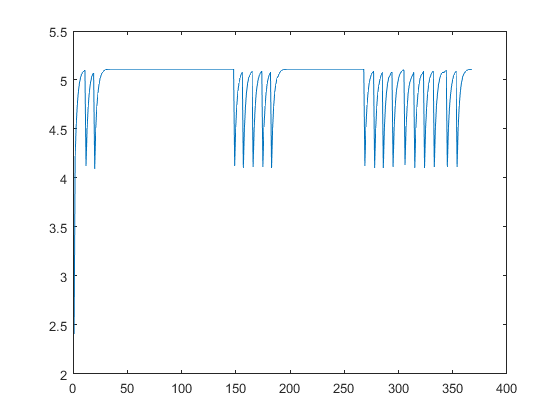


figure();
plot(states_end_list(4,:));

% for m= 1: length(u_burn_list)
% plot(u_burn_list(:,m));
% hold on;
% end
% hold off;
% 
% figure()
% for m= 1: length(u_burn_list)
% plot(u_f_dri_list(:,m));
% hold on;
% end